
data = readtable('C:\Users\SUDARSHAN\Downloads\TCGA_LAML_PCA_READY.csv');

X = table2array(data);

X_scaled = (X - mean(X)) ./ std(X);

[coeff, score, latent, tsquared, explained, mu] = pca(X_scaled);



fprintf('Explained Variance Ratio per component:\n');

Explained Variance Ratio per component:


for i = 1:3
    fprintf('  PC%d: %.4f (%.2f%%)\n', i, explained(i)/100, explained(i));
end

  PC1: 0.3410 (34.10%)
  PC2: 0.1912 (19.12%)
  PC3: 0.1516 (15.16%)


fprintf('  Total Variance Explained (3 PCs): %.2f%%\n', sum(explained(1:3)));

  Total Variance Explained (3 PCs): 68.38%


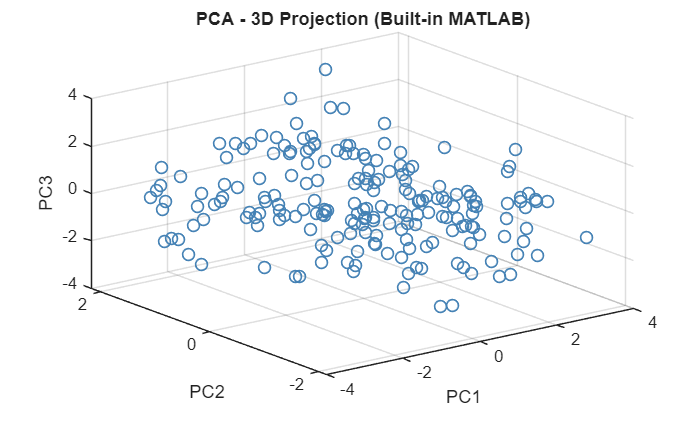


figure;
scatter3(score(:,1), score(:,2), score(:,3), ...
         50, 'o', 'MarkerEdgeColor', [0.27 0.51 0.71], ...
         'MarkerFaceColor', 'none', 'LineWidth', 1);

xlabel('PC1');
ylabel('PC2');
zlabel('PC3');
title('PCA - 3D Projection (Built-in MATLAB)');
grid on;